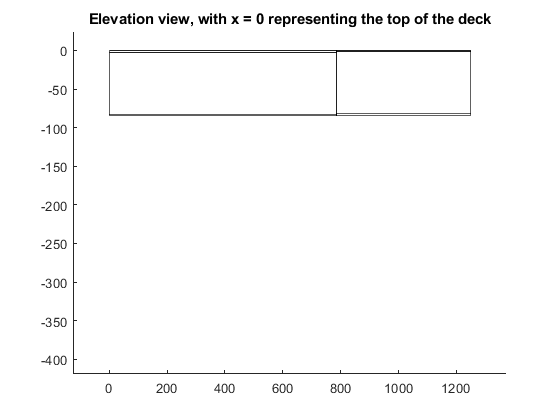

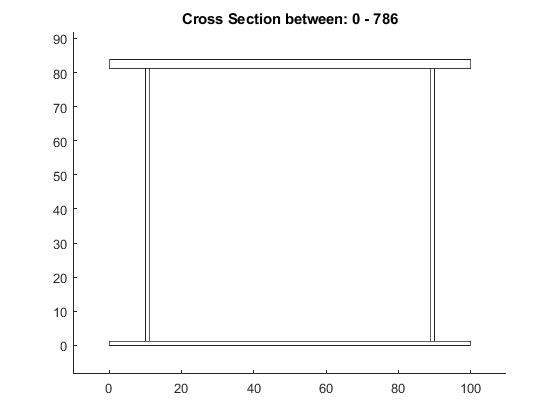

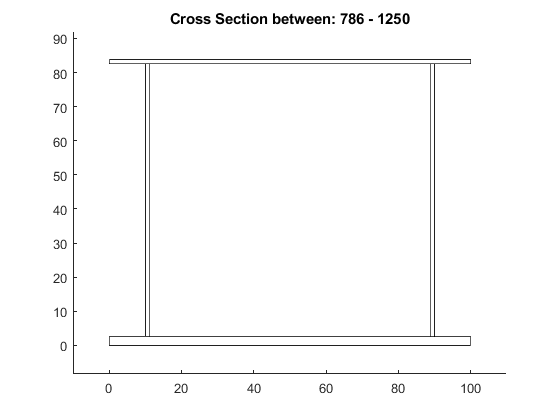

%% 0. Initialize Parameters 
n = 1250; % Dont change                  % Number of locations to evaluate bridge failure 
L = 1250;                  % Length of bridge 

%%%%%%%%%%% ALL VALUES ARE IN TERMS OF P, BUT JUST NEED TO WRITE "P" AT THE
%%%%%%%%%%% END


x = linspace(0, L, n);     % Define x coordinate 
SFD_PL = zeros(1, n);      % Initialize SFD(x) 
  
%% 1. Point Loading Analysis (SFD, BMD) 

% Calculate Forces
xP = [550, 1250];
P = [1, 1]; 
% Calculate Supports
xS = [0, 1060];
S = [0, 0];
[S(1), S(2)] = CalcSupportForces( xP, P, xS );

  
%% 2. Define cross-sections 
% There are many (more elegant ways) to construct cross-section objects 
xc = [0 786 L];  % Location, x, of cross-section change 
bft = [100 100 100]; % Top Flange Width 
tft = [1.27*2 1.27 1.27]; % Top Flange Thickness 
hw = [80, 80, 80];  % Web Height 
tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs) 
spacing_web = [80 80 80]; % Includes width of the Flange
bfb = [100 100 100];  % Bottom Flange Width 
tfb = [1.27 1.27*2 1.27*2]; % Bottom Flange Thickness 
a = [0 150 300 450 600 750 900 1050 1200 1350 2000];   % Position of Diaphrams

% Optional but you need to ensure that your geometric inputs are correctly implemented 
VisualizeBridge( xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a );  

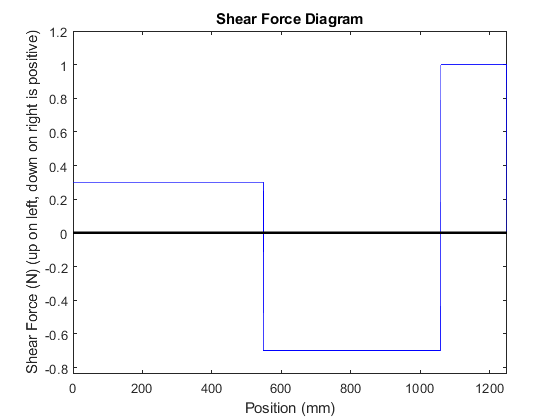

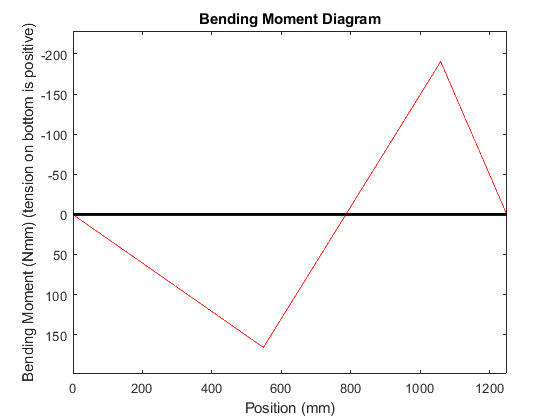

 

%[SFD_PL, BMD_PL] = ApplyPL(550, P, x, SFD_PL);      % Construct SFD, BMD 
%[SFD_PL, BMD_PL] = ApplyPL(L, P, x, SFD_PL);        % Construct SFD, BMD 
[SFD, BMD] = ApplyPL(x,xP,P,xS,S);
graphSFDBMD(x, SFD, BMD)



%% 3. Define Material Properties 
SigT = 30; 
SigC = 6; 
E    = 4000; 
TauU = 4; 
TauG = 2; 
mu   = 0.2;


h = [1.27 1.27 1.27 75-3*1.27 75-3*1.27 1.27]; %for debugging
b = [100 10 10 1.27 1.27 80]; %for debugging 
areas = b.*h;

distances = [(75-1.27/2) 75-1.27-(1.27/2) 75-1.27-(1.27/2) (75-1.27)/2 (75-1.27)/2 1.27/2];

y_bar = CalculateYBar(areas, distances);
y_vector = repmat(y_bar, 1250, 1);



%I = CalcI(b,h,y_bar, distances);
[y_bar_vector, I_vector] = Calc_Cross_Section_Properties(xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a)

y_bar_vector =    50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589   50.1589


I_vector = 	1.0e+05 *

    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477    7.0477


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%TEMP%%%%%%%%%%%%%%%%
I_vector = ones(1, 1250)*784*10^3

I_vector =       784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000



bottom_areas_real = [80*1.27 (y_vector(1,1)-1.27).*(1.27) (y_vector(1,1)-1.27).*(1.27)];
bottom_areas = [80*1.27 (y_bar_vector(1,1)-1.27).*(1.27) (y_bar_vector(1,1)-1.27).*(1.27)];
bottom_dist_from_centroid_real = [tfb(1,1)/2-y_vector(1,1) (y_vector(1,1)-tfb(1,1))./2-y_vector(1,1) (y_vector(1,1)-tfb(1,1))./2-y_vector(1,1)];
bottom_dist_from_centroid = [tfb(1,1)/2-y_bar_vector(1,1) (y_bar_vector(1,1)-tfb(1,1))./2-y_bar_vector(1,1) (y_bar_vector(1,1)-tfb(1,1))./2-y_bar_vector(1,1)]; 
bottom_areas = repmat(bottom_areas,1250,1);
bottom_areas_real = repmat(bottom_areas_real,1250,1);
bottom_dist_from_centroid_real = repmat(bottom_dist_from_centroid_real,1250,1);

bottom_dist_from_centroid = repmat(bottom_dist_from_centroid,1250,1);
b = repmat(1.27,1250,1);
I_vec = I_vector %let I be constant for design zero 

I_vec =       784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000      784000


top_area = 1.27*100;
top_area = repmat(top_area, 1250, 1);
top_dist_from_centroid = 75-1.25/2-y_vector(1,1);
top_dist_from_centroid = repmat(top_dist_from_centroid, 1250, 1);
Qcent = CalcQcent(bottom_areas_real, bottom_dist_from_centroid_real);%for debugging, for design 0 
Qglue = CalcQglue(top_area, top_dist_from_centroid);
[Ybot, Ytop] = CalcYbotYtop(h(1), y_bar);
Ybot_vec = Ybot*ones(1,1250);
Ytop_vec = Ytop*ones(1,1250);

%%%
diaphragm_spacing = [550 510 190];
I_v = I_vec(1:4)

I_v =       784000      784000      784000      784000



%% 1. FLEXURAL FAILURES


%% 2. SHEAR FAILURES


%% 3. GLUE SHEAR FAILURES


%% 4. PLATE BUCKLING FAILURES
[P_Plate_Buck_Vector, M_Plate_Buck_Vector, M_Plate_Buck_Matrix] = Calc_MFail_Buck_Over_Entire_Bridge(xc, bft, tft, hw, tw, spacing_web, bfb, tfb, I_v, E, BMD, y_bar_vector)

P_Plate_Buck_Vector = 	1.0e+06 *

    1.1812    0.5906    0.3937    0.2953    0.2362    0.1969    0.1687    0.1476    0.1312    0.1181    0.1074    0.0984    0.0909    0.0844    0.0787    0.0738    0.0695    0.0656    0.0622    0.0591    0.0562    0.0537    0.0514    0.0492    0.0472    0.0454    0.0437    0.0422    0.0407    0.0394    0.0381    0.0369    0.0358    0.0347    0.0337    0.0328    0.0319    0.0311    0.0303    0.0295    0.0288    0.0281    0.0275    0.0268    0.0262    0.0257    0.0251    0.0246    0.0241    0.0236


M_Plate_Buck_Vector = 	1.0e+05 *

    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687    3.5687


M_Plate_Buck_Matrix = 	1.0e+06 *

    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750    2.2750
    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0.3569    0

P_Plate_Buck = min(P_Plate_Buck_Vector)

P_Plate_Buck = 1.2096e+03

%% 5. SHEAR BUCKLING FAILURES






  
%% 4. Calculate Failure Moments and Shear Forces 
% V_Mat = Vfail({CrossSectionInputs}, TauU); 
% V_Glue = VfailGlue({CrossSectionInputs}, TauU); 
% V_Buck = VfailBuck({CrossSectionInputs}, E, mu ); 
%   
% M_MatT = MfailMatT({CrossSectionInputs}, SigT); 
% M_MatC = MfailMatC({CrossSectionInputs}, SigC); 
% M_Buck1 = MfailBuck({CrossSectionInputs}, E, mu, 1 ); 
% M_Buck2 = MfailBuck({CrossSectionInputs}, E, mu, 2 ); 
% M_Buck3 = MfailBuck({CrossSectionInputs}, E, mu, 3 ); 
  


%% 4.7 Calculate Failure Load 
% Pf = FailLoad(P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3); 
  
%% Visualization 
% VisualizePL(x, P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf); 
  
%% 5. Curvature, Slope, Deflections 
% Defls = Deflections(x, BMD_PL, I, E); 


[P_buck, VBuck] = Calc_VBuck_New(SFD, xc, tw, hw, Qcent, a, 0.2, E, I_vector)

V_shear_buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_shear_buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_buck = 	1.0e+05 *

    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566    1.5566


VBuck = 	1.0e+04 *

    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993    4.6993


%[P_buck, VBuck] = Calc_VBuck(tw, hw, diaphragm_spacing, mu, SFD,I_vec, b(1:4), Qcent(1:4), xc)%for design 0 

%%%

%%%
[P_tension, MatT] = MfailMatT(Ybot_vec, Ytop_vec, I_vec, SigT, BMD); %insert Ybot, Ytop, I as vectors 
[P_compression, MatC] = MfailMatC(Ybot_vec, Ytop_vec, I_vec, SigC, BMD); %insert Ybot, Ytop, I as vectors 
[P_shear, VFail] = CalcVfail(Qcent, I_vec, b, TauU, SFD);
b_glue = repmat((10+1.27)*2,1250,1); %base length of the glue portion 

[P_shear_glue, VFail_glue] = CalcVfail(Qglue, I_vec, b_glue, TauG, SFD);
%%%

%%% 


P = 200;
P_fail = FailLoad(P,SFD, BMD, P_shear, P_buck, P_tension, P_compression, P_Plate_Buck_Vector)

min_P_shear = 0

min_P_buck = 1.1889e+04

min_P_tension = 3.0721e+03

min_P_compression = 595.6027

min_P_plate_buck = 1.2096e+03

P_fail = 0

BMD(675)

ans = 77.8359

Sign_of_BMD =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


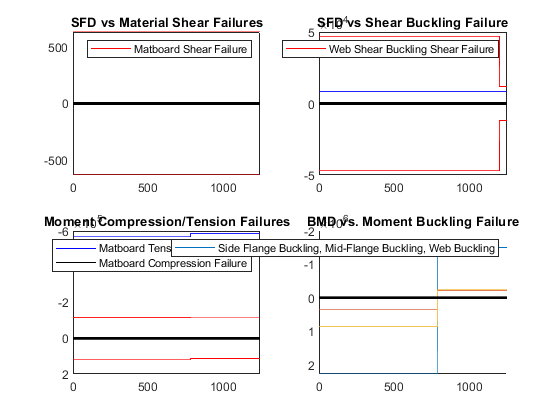

t = repmat(1.27, 1250, 1);
%[P_fail_buckle, M_fail_buckle] = MfailBuck(t,I, case_num, E, BMD, Ytop_vec, Ybot_vec)  
VisualizePL(P_fail,SFD, BMD, VFail, VBuck, MatT, MatC, VFail_glue, M_Plate_Buck_Matrix)  

defls = Deflections(BMD, I_vec, E , 200) 

a_to_b = 1060

defls = 0.7201


%% TRAIN LOADING
Max_SFD = zeros(1, 1250)

Max_SFD =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Min_SFD = zeros(1, 1250)

Min_SFD =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Max_BMD = zeros(1, 1250)

Max_BMD =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Min_BMD = zeros(1, 1250)

Min_BMD =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P = [400/6, 400/6, 400/6, 400/6, 400/6, 400/6]

P =    66.6667   66.6667   66.6667   66.6667   66.6667   66.6667


xP = [0, 176, 340, 516, 680, 856]

xP =      0   176   340   516   680   856


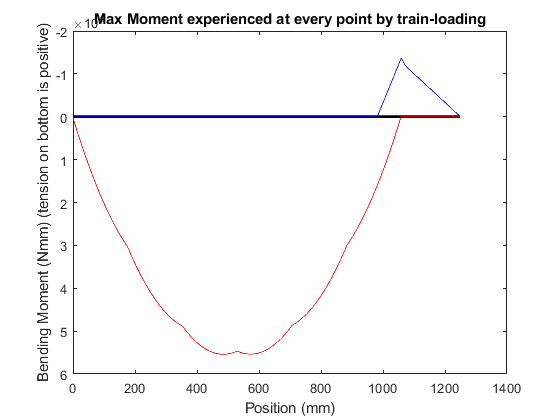

for pos = 1:1250-856
    [Ay By] = CalcSupportForces(xP+pos, P, xS);
    [SFD, BMD] = ApplyPL(x,xP+pos,P,xS, [Ay By]);
    
    for element=1:1250
        Max_BMD(element) = max([Max_BMD(element), BMD(element)]);
        Min_BMD(element) = min([Min_BMD(element), BMD(element)]);
        Max_SFD(element) = max([Max_SFD(element), SFD(element)]);
        Min_SFD(element) = min([Min_SFD(element), SFD(element)]);
    end
    
    
end

figure
plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
hold on
plot(x, Max_BMD, "r")
plot(x, Min_BMD, "b")
set(gca, 'YDir','reverse')
title("Max Moment experienced at every point by train-loading")
ylabel("Bending Moment (Nmm) (tension on bottom is positive)")
xlabel("Position (mm)")
hold off

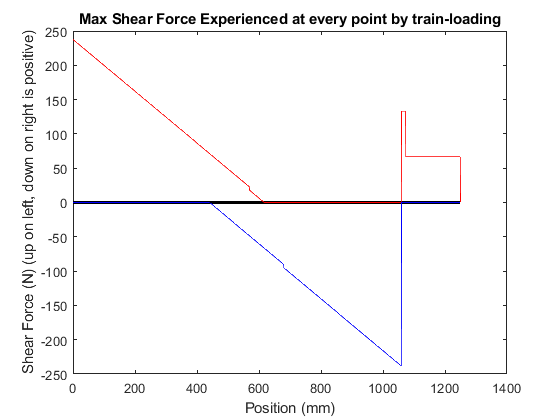


figure
plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
hold on
plot(x, Max_SFD, "r")
plot(x, Min_SFD, "b")
title("Max Shear Force Experienced at every point by train-loading")
ylabel("Shear Force (N) (up on left, down on right is positive)")
xlabel("Position (mm)")
hold off

function [ y_bar ] = CalculateYBar (areas, distances)
    y_bar = sum((areas .* distances)) / sum(areas);
end

function [ I ] = CalcI(b,h,y_bar, dists_from_centroid) %b, h, dist_from_centroid are all vectors
    I = sum(b.*h.^3/12) + sum(b.*h.*(dists_from_centroid-y_bar).^2); %assuming all of the components are rectangles 
end 

%%%%%%%%%%%%%%%%%ADD CALCULATION FOR DIAPHRAMS
function [ y_bar_vector, I_vector ] = Calc_Cross_Section_Properties(xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a)
    I_vector = zeros(1,xc(end));
    y_bar_vector = zeros(1,xc(end));
    for interval = 1:length(xc) - 1
        % Assume Flaps used for gluing are not significant
        %    Base of top,   total base of web, base of bot
        b = [bft(interval), tw(interval), tw(interval), bfb(interval)];
        h = [tft(interval), hw(interval), hw(interval), tfb(interval)];
        areas = b.*h;
        heights = [hw(interval)+tfb(interval)+tft(interval)/2, (tfb(interval)+hw(interval))/2, (tfb(interval)+hw(interval))/2, tfb(interval)/2];
        for x_value = xc(interval)+1:xc(interval + 1)
            y_bar_vector(x_value) = CalculateYBar( areas, heights);
            I_vector(x_value) = CalcI(b, h, y_bar_vector(x_value), heights);
           
        end
    end
    %     xc = [0 550 L];  % Location, x, of cross-section change 
%     bft = [100 100 100]; % Top Flange Width 
%     tft = [2.54 2.54 2.54]; % Top Flange Thickness 
%     hw = [100 120 100];  % Web Height 
%     tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs) 
%     spacing_web = [80 80 80]; % Includes width of the Flange
%     bfb = [80 80 80];  % Bottom Flange Width 
%     tfb = [1.27 1.27 1.27]; % Bottom Flange Thickness 
%     a = [400 400 400];   % Diaphragm Spacing 
    
end

function [ Ay By ] = CalcSupportForces( xP, P, xS )
    % Calculate the support forces in "N"s
    By = sum((xP-xS(1)).*P) / xS(2) - xS(1);
    %By = sum((xP - dist_A_to_B).*P) % Clockwise Positive
    Ay = sum(P)-By;
end

function [ BMD ] = CalculateBMD(SFD, x)
    BMD = cumsum(SFD)*((x(2)-x(1))/1); % Convert to mm
end

function [ SFD, BMD ] = ApplyPL( x, xP, P, xS, S )
    dist_A_to_B = xS(2) - xS(1);
    SFD = S(1)*ones(1,1250);
    for load=1:length(xP)
        SFD(xP(load):end) = SFD(xP(load):end)-P(load);
    end
    SFD(dist_A_to_B:end) = SFD(dist_A_to_B:end) + S(2);

    %want to plot BMD and SFD 
    BMD = CalculateBMD(SFD, x);
    %BMD(xP) = BMD(1)-SFD(xP).*xP
    %BMD(dist_A_to_B) = BMD(xP)-SFD(xP).*(dist_A_to_B-xP(i))
    
    % PLOT SFD
    %SFD(1) = 0; % Just to make the graph pretty
    %SFD(end) = 0;
end 

function graphSFDBMD(x, SFD, BMD)
    max_SFD = max(SFD);
    max_BMD = max(BMD);
    min_SFD = min(SFD);
    min_BMD = min(BMD);
    plot(x,SFD, "b")
    hold on
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    axis([0, 1250, min(SFD) * 1.2, max(SFD) * 1.2])
    title("Shear Force Diagram")
    ylabel("Shear Force (N) (up on left, down on right is positive)")
    xlabel("Position (mm)")
    hold off    
    
    % PLOT BMD
    figure
    plot(x,BMD,"r")
    set(gca, 'YDir','reverse')
    hold on
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    axis([0, 1250, min(BMD) * 1.2, max(BMD) * 1.2])
    title("Bending Moment Diagram")
    ylabel("Bending Moment (Nmm) (tension on bottom is positive)")
    xlabel("Position (mm)")
    hold off
end


% Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports 
% Input: location and magnitude of point load. The previous SFD can be entered as input to  
%  construct SFD of multiple point loads 

% Output: SFD, BMD both 1-D arrays of length n 


function [  ] = VisualizeBridge( xc, bft, tft, hw, tw, spacing_web, bfb, tfb, a ) 
% Optional. Provides a graphical interpretation of user geometric inputs 
    
    % Assuming that the maximum width of the beam will be either the top or
    % bottom flange:
    max_width = max(max(bft), max(bfb));
    max_height = max(tft + tfb + hw);

    %% Draw out the Elevation View
    figure
    for i = 1:length(xc) -1
        rectangle('Position', [xc(i), -tft(i), xc(i+1) - xc(i),  tft(i)]) % Draw the Top Flange
        rectangle('Position', [xc(i), -tft(i)-hw(i), xc(i+1) - xc(i),  hw(i)]) % Draw the Web
        rectangle('Position', [xc(i), -tft(i)-hw(i)-tfb(i), xc(i+1) - xc(i),  tfb(i)]) % Draw the Bottom Flange
    end
    axis([(xc(end) - xc(1)) * (-0.1), (xc(end) - xc(1)) * 1.1, max_height * (-5), max_height * 0.3])
    title("Elevation view, with x = 0 representing the top of the deck")

    %% Draw out the cross-section in each interval    
    for i = 1:length(xc) -1
        figure
        rectangle('Position', [0, hw(i)+tfb(i), bft(i),  tft(i)]) % Draw the Top Flange
        rectangle('Position', [(bft(i) - bfb(i)) / 2, 0, bfb(i),  tfb(i)]) % Draw the Bottom Flange
        rectangle('Position', [((max_width / 2) - (spacing_web(i) / 2)), tfb(i), tw(i), hw(i)]) % Draw the Left-Side of the Web
        rectangle('Position', [((max_width / 2) + (spacing_web(i) / 2))- tw(i), tfb(i), tw(i), hw(i)]) % Draw the Right-Side of the Web
        
        axis([max_width * (-0.1), max_width * 1.1, max_height * (-0.1), max_height * 1.1])
        title("Cross Section between: " + xc(i) + " - " + xc(i+1))
    end
end



%  function [ {Sectional Properties} ] = SectionProperties( {Geometric Inputs} ) % Calculates important sectional properties. Including but not limited to ybar, I, Q, etc. 
% % Input: Geometric Inputs. Format will depend on user 
% % Output: Sectional Properties at every value of x. Each property is a 1-D array of length n 
%  
% function [ V_fail ] = Vfail( {Sectional Properties}, TauU ) 
% % Calculates shear forces at every value of x that would cause a matboard shear failure 
% % Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% % Output: V_fail a 1-D array of length n 
%     I = {Sectional Properties}; 
%     b = {Sectional Properties}; 

function [Qcent] = CalcQcent(top_areas, local_centroidal_heights) %calculating from the top , calculate local_centroidal_heights of the top half of the structure beforehand 
    Qcent = nan(1,1250); %rows of the top_areas are the areas for individual cross section 
    test = top_areas .* local_centroidal_heights;
    Qcent = abs(sum(test,2));
end
function [Qglue] = CalcQglue(top_area, local_centroidal_height)
    Qglue = top_area.*local_centroidal_height;
end 
%  function [ {Sectional Properties} ] = SectionProperties( {Geometric Inputs} ) % Calculates important sectional properties. Including but not limited to ybar, I, Q, etc. 
% % Input: Geometric Inputs. Format will depend on user 
% % Output: Sectional Properties at every value of x. Each property is a 1-D array of length n 
%  

function [ P_fail, V_fail] = CalcVfail( Qcent, I, b, Shear_failure, SFD) %need to be able to accomodate for Qglue as well 
% % Calculates shear forces at every value of x that would cause a matboard shear failure 
% % Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% % Output: V_fail0)
    V_fail = nan(1,1250);
    P_fail = nan(1,1250);
    for i = 1:1250
        
        V_fail(i) = Shear_failure .* I(i) .* b(i) ./ Qcent(i);
        if SFD(i) == 0
            P_fail(i) = 0;
        else
            P_fail(i) = V_fail(i) ./ SFD(i);
            
        end
        %give out result in newtons 
    end
               
end 

function [ybot, ytop] = CalcYbotYtop(height, y_bar)
    ybot = y_bar;
    ytop = height - y_bar;
end



function [ P_fail_tension, M_fail_tension ] = MfailMatT( ybot, ytop, I, SigT, BMD )  
% % Calculates bending moments at every value of x that would cause a matboard tension failure 
% % Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array) 
% % Output: M_MatT a 1-D array of length n 
    M_fail_tension = zeros(1,1250);
    for i = 1 : 1250    
        if BMD(i) > 0 % If the moment is positive, the tension failure will be at the bottom 
            M_fail_tension(i) = SigT * I(i) / ybot(i); 
        elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_fail_tension(i) = -SigT * I(i) / ytop(i);
        end
    end 
    P_fail_tension = M_fail_tension ./ BMD;
    P_fail_max = max(P_fail_tension);


end 

function [ P_fail_compression, M_fail] = MfailMatC(ybot, ytop, I, Stress_fail, BMD) % Similar to MfailMatT 
      M_fail = zeros(1,1250);
      
      for i = 1 : 1250
            if BMD(i) > 0 % If the moment is positive, the tension failure will be at the bottom 
                M_fail(i) = Stress_fail * I(i) / ytop(i); 
            elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at the top 
                M_fail(i) = -Stress_fail * I(i) / ybot(i); 
            end 
      end 
      
      P_fail_compression = M_fail ./ BMD;

end

function [P_shear_buck, V_shear_buck] = Calc_VBuck_New(SFD, xc, tw, hw, Qcent, a_positions, poisson, E, I)
    section = 1;
    which_a = 1;
    V_shear_buck = zeros(1, 1250)
    P_shear_buck = zeros(1, 1250)
    for pos = 1:1250
        if pos > xc(section+1)
            section = section + 1;
        end
        if pos > a_positions(which_a)
            which_a = which_a + 1;
        end
        tau = (5 * pi^2 * E)/(12*(1-poisson^2)) * ((tw(section)/hw(section))^2 + (tw(section)/(a_positions(which_a+1)-a_positions(which_a))));
        V_shear_buck(pos) = tau*I(pos)*tw(section)*2/Qcent(pos);
        P_shear_buck(pos) = V_shear_buck(pos)/SFD(pos);
    end
end

function [Force_Buck_vec, v_buck_vec] = Calc_VBuck(t,h,a,mu,SFD,I,b,Qcent,xc)
        stress_buck = nan(1,length(h));

        v_buck = nan(1,length(h));
        Force_Buck = nan(1,length(h));
        Force_Buck_vec = nan(1,1250);
        
        index = cumsum(a);

        E = 4000 %modulus of elasiticity 
        for i = 1:length(v_buck)
            stress_buck(i) = 5*pi.^2*E./(12*(1-mu.^2)).*((t(i)/h(i)).^2+(t(i)./a(i)).^2);
            v_buck(i) = stress_buck(i).* I(xc(i)+1) .* b(i) ./ Qcent(i);
            Force_Buck(i) = v_buck(i)./abs(SFD(index(i)));        
        end 
        Force_Buck_vec(1:index(1)) = Force_Buck(1);
        Force_Buck_vec(index(1):index(2)) = Force_Buck(2);
        Force_Buck_vec(index(2):index(3)) = Force_Buck(3);
        v_buck_vec(1:index(1)) = v_buck(1);
        v_buck_vec(index(1):index(2)) = v_buck(2);
        v_buck_vec(index(2):index(3)) = v_buck(3);
        
end 

function [P_fail, M_fail, M_Plate_Buck_Matrix] = Calc_MFail_Buck_Over_Entire_Bridge(xc, bft, tft, hw, tw, spacing_web, bfb, tfb, I_vector, E, BMD, y_bar) 
%     Assume each section is independant of the other, and do not consider the
%     extra length uesd to glue two pieces together. Calculate Buckling load
%     at each point along the bridge
    
    P_fail = ones(1, length(BMD))*100000000000;
    M_fail = ones(1, length(BMD))*100000000000;
    M_Plate_Buck_Matrix = zeros(3, length(BMD)); % Left/Right of Flange, Center of flange, Webs
    for section = 1:length(bft)-1
        for i = xc(section)+1:xc(section+1)
            % Compression at top
            if BMD(i) > 0
                % 5 Plates to check (3 on the top flange, 2 on the webs)
                % 3 On the Top Flange (Assume that it is symmetrical):
                % 2 On the webs:
                
                % Top Left and top right of the flange
                if (bft(section)- spacing_web(section))/2 > 0
                    [potential_P_fail, potential_M_fail] = MfailBuck_Slice(tft(section), (bft(section)- spacing_web(section))/2, I_vector(section), 2, E, BMD(i), tfb(section)+hw(section)+tft(section)/2-y_bar(section), 0.2);
                    P_fail(i) = min([P_fail(i), potential_P_fail]);
                    M_fail(i) = min([potential_M_fail, M_fail(i)]);
                    M_Plate_Buck_Matrix(1,i) = potential_M_fail;
                    
                end
                % Center of the top flange
                [potential_P_fail, potential_M_fail] = MfailBuck_Slice(tft(section), (spacing_web(section)-2*tw(section)), I_vector(section), 1, E, BMD(i), tfb(section)+hw(section)+tft(section)/2-y_bar(section), 0.2);
                P_fail(i) = min([P_fail(i), potential_P_fail]);
                M_fail(i) = min([potential_M_fail, M_fail(i)]);
                M_Plate_Buck_Matrix(2,i) = potential_M_fail;
                
                % Webs
                [potential_P_fail, potential_M_fail] = MfailBuck_Slice(tw(section), tfb(section)+hw(section)-y_bar(section), I_vector(section), 3, E, BMD(i), tfb(section)+hw(section)-y_bar(section), 0.2);
                P_fail(i) = min([P_fail(i), potential_P_fail]);
                M_fail(i) = min([potential_M_fail, M_fail(i)]);
                M_Plate_Buck_Matrix(3,i) = potential_M_fail;
                
            else % Compression at the bottom
                % 5 Plates to check (3 on the bottom flange, 2 on the webs)
                % 3 On the Bottom Flange (Assume that it is symmetrical):
                % 2 On the webs:
                
                % Bottom Left and Bottom right of the flange
                if (bfb(section)- spacing_web(section))/2 > 0
                    [potential_P_fail, potential_M_fail] = MfailBuck_Slice(tfb(section), (bfb(section)- spacing_web(section))/2, I_vector(section), 2, E, -BMD(i), y_bar(section)-tfb(section/2), 0.2);
                    P_fail(i) = min([P_fail(i), potential_P_fail]);
                    M_fail(i) = min([potential_M_fail, M_fail(i)]);
                    M_Plate_Buck_Matrix(1,i) = potential_M_fail;
                end
                %Center of the Bottom flange
                [potential_P_fail, potential_M_fail] = MfailBuck_Slice(tfb(section), (spacing_web(section)-2*tw(section)), I_vector(section), 1, E, -BMD(i), y_bar(section), 0.2);
                P_fail(i) = min([P_fail(i), potential_P_fail]);
                M_fail(i) = min([potential_M_fail, M_fail(i)]);
                M_Plate_Buck_Matrix(2,i) = potential_M_fail;
                
                % Webs
                [potential_P_fail, potential_M_fail] = MfailBuck_Slice(tw(section), y_bar(section)-tfb(section), I_vector(section), 3, E, -BMD(i), y_bar(section)-tfb(section), 0.2);
                P_fail(i) = min([P_fail(i), potential_P_fail]);
                M_fail(i) = min([potential_M_fail, M_fail(i)]);
                M_Plate_Buck_Matrix(3,i) = potential_M_fail;
                
                
            end
        end
    end
        
%    % 10 Plates to check to see if there is buckling.
%    Mfail_vect = zeros(1,10)
%    P_fail_vect = zeros(1, 10)
%    % 3 Plates on the Top Flange (Assume that it is symmetrical):
%    width = (bft - spacing_webs)/2
%    [P_fail_vect(1) = MfailBuck
   
end

function [P_fail, M_fail] = MfailBuck_Slice(thickness,width, I, case_num, E, Moment, y_to_centroid, poisson)
    if case_num == 1
        sigma_crit = ((4 * (pi ^ 2) * E) / (12 * (1 - poisson^2)))  * ((thickness/width) ^ 2);
    elseif case_num == 2
        sigma_crit = ((0.425 * (pi ^ 2) * E) / (12 * (1 - poisson^2)))  * ((thickness/width) ^ 2);
    else
        sigma_crit = ((6 * (pi ^ 2) * E) / (12 * (1 - poisson^2)))  * ((thickness/width) ^ 2);
    end
    M_fail = sigma_crit * I / y_to_centroid;
    P_fail = M_fail/Moment;
end


function [P_fail, M_fail] = MfailBuck(t,b, I, case_num, E, BMD, Ytop_vec, Ybot_vec) 
    %Assume each section is independant of the other, and do not consider the
    %extra length uesd to glue two pieces together
    %there are 3 different cases to consider for 8 different plate sections
    if case_num == 1
        for i = length(BMD)
            if BMD(i) < 0
                y_compression = y_top_vec(i)
            else 
                y_compression = y_bot_vec(i)
            end
           
            shear_buckle_1(i) = 4.*pi.^2.*E./(12.*(1-0.2.^2).*(t(i)./b(i)).^2)
            M_fail_1(i) = shear_buckle_1.*I(i)./y_compression(i)
            P_fail_1(i) = M_fail ./BMD(i)
        end 
    elseif case_num == 2
        for i = length(BMD)
            if BMD(i) < 0
                    y_compression = y_top_vec(i)
                else 
                    y_compression = y_bot_vec(i)
                end
            shear_buckle_2 = 0.425.*pi.^2.*E./(12.*(1-0.2.^2).*(t./b).^2)
            M_fail_3(i) = shear_buckle_1.*I(i)./y_compression(i)
            P_fail_3(i) = M_fail ./BMD(i)
        end 
    elseif case_num == 3
        for i = length(BMD)
            if BMD(i) < 0
                y_compression = y_top_vec(i)
            else 
                y_compression = y_bot_vec(i)
            end
            shear_buckle_3 = 6.*pi.^2.*E./(12.*(1-0.2.^2).*(t./b).^2)
            M_fail_3(i) = shear_buckle_1.*I(i)./y_compression(i)
            P_fail_3(i) = M_fail ./BMD(i)
        end 

    end

end
% Calculates bending moments at every value of x that would cause a buckling failure 
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property), BMD (1-D array) 
% Output: M_MatBuck a 1-D array of length n 

function [ Pf ] = FailLoad( P,SFD, BMD, P_shear, P_buck, P_tension, P_compression, P_Plate_Buck_Vector)  %M_Buck1, M_Buck2, M_Buck3 calculate m buck afterwords 
    min_P_shear = min(abs(P_shear))
    min_P_buck = min(abs(P_buck))
    min_P_tension = min(abs(P_tension))
    min_P_compression = min(abs(P_compression))
    min_P_plate_buck = min(abs(P_Plate_Buck_Vector))
    min_Ps = [min_P_shear, min_P_buck, min_P_tension,min_P_compression, min_P_plate_buck];
    
    Pf = min(min_Ps);

end 
    
% % Calculates the magnitude of the load P that will cause one of the failure mechanisms to occur 
% % Input: SFD, BMD under the currently applied points loads (P) (each 1-D array of length n) 
% %  {V_Mat, V_Glue, ... M_MatT, M_MatC, ... } (each 1-D array of length n) 
% % Output: Failure Load value Pf 
function [] = VisualizePL(P,SFD, BMD, Vfail, Vbuck, M_MatT, M_MatC, VFail_glue, M_Plate_Buck_Failure_Matrix)  
    n = 1250;                  % Number of locations to evaluate bridge failure 
    L = 1250;                  % Length of bridge 
    x = linspace(0, L, n); 
    Sign_of_BMD = (BMD > 0) * 2 - 1
    
    subplot(2,2,1)
    plot(x,Vfail,"r")
    hold on 
    plot(x,-Vfail,"r")
    
    
    hold on 
    plot(x,SFD.*P,"k")
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    
    xlim([0,1250])
    %axis([0, 1250, min_y * 1.2, max_y * 1.2])
    title("SFD vs Material Shear Failures")
    legend("Matboard Shear Failure")

    hold off    
    
    
    
    subplot(2,2,2)
    plot(x,Vbuck,"r")
    hold on 
    plot(x,-Vbuck,"r")
    hold on 
    if min(VFail_glue) < min(Vbuck) % would plot the glue shear failure only if hte value is less than Vbuck 
        plot(x,VFail_glue, "b")
        hold on 
    end 
    plot(x,SFD.*P,"k")
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)

    xlim([0,1250])
    title("SFD vs Shear Buckling Failure")
    legend("Web Shear Buckling Shear Failure")
    hold off    
    
    subplot(2,2,3)
    plot(x,M_MatT,"b")
    plot(x,-M_MatT,"b")
    hold on 
    plot(x,BMD.*P,"k")
    hold on 
    plot(x,M_MatC,"r")
    plot(x,-M_MatC,"r")
    hold on 
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    set(gca, 'YDir','reverse')

    title("Moment Compression/Tension Failures")
    legend("Matboard Tension Failure", "Matboard Compression Failure")
    
    xlim([0 1250])

    hold off     
    
    subplot(2,2,4)
    hold on
    plot(x,M_Plate_Buck_Failure_Matrix .* Sign_of_BMD);
    plot(x,BMD.*P,"k")
    hold on 
    plot(x, zeros(1, length(x)), "k", "lineWidth", 2)
    legend("Side Flange Buckling, Mid-Flange Buckling, Web Buckling")
    title("BMD vs. Moment Buckling Failure")
    
    hold off 
    xlim([0 1250])    
    set(gca, 'YDir','reverse')


   
    

end 
% % Plots all outputs of design process 

function [ Defl ] = Deflections(BMD, I, E , P)  %x is the position of the midspan 
    mid = 530;
    a_to_b = 530*2 %midspan 
    curvature = BMD./(I.*E).*P;
    curvature(1060);
    delta_C_A = 1/2*550*curvature(550)*(1/3*550+510)+1/2*curvature(550)*237*(2/3*237+273)+(1/2*curvature(1060)*1/3*(273)*273);
    delta_mid_A = 1/2*mid*curvature(530)*(1/3*530);
    Defl = 1/2*delta_C_A - delta_mid_A;
end 

% % Calculates deflections 
% % Input: I(1-D arrays), E (material property), BMD (1-D array) 
% % Output: Deflection for every value of x (1-D array) or for the midspan only  


